# Optimización utilizando un algoritmo genético (GA) en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez


                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations


    1              100          -2.448         -0.9857        0


    2              147          -2.448          -1.508        1


    3              194          -2.448          -1.583        2


    4              241          -2.448          -1.928        3


    5              288          -2.448          -1.905        4


    6              335          -2.448          -1.851        5


    7              382          -2.448          -2.075        6


    8              429          -2.448          -2.225        7


    9              476          -2.448          -2.225        8


   10              523          -2.448          -2.318        9


   11              570           -2.45          -2.407        0


   12              617           -2.45          -2.418        1


   13              664           -2.45          -2.447        2


   14              711           -2.45          -2.448        3


   15              758           -2.45           -2.45        0


   16              805           -2.45           -2.45        1


   17              852           -2.45           -2.45        2


   18              899           -2.45           -2.45        0


   19              946           -2.45           -2.45        1


   20              993           -2.45           -2.45        2


   21             1040           -2.45           -2.45        0


   22             1087           -2.45           -2.45        1


   23             1134           -2.45           -2.45        2


   24             1181           -2.45           -2.45        3


   25             1228           -2.45           -2.45        4


   26             1275           -2.45           -2.45        5


   27             1322           -2.45           -2.45        6


   28             1369           -2.45           -2.45        7


   29             1416           -2.45           -2.45        8


   30             1463           -2.45           -2.45        9

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations


   31             1510           -2.45           -2.45       10


   32             1557           -2.45           -2.45       11


   33             1604           -2.45           -2.45       12


   34             1651           -2.45           -2.45       13


   35             1698           -2.45           -2.45       14


   36             1745           -2.45           -2.45       15


   37             1792           -2.45           -2.45       16


   38             1839           -2.45           -2.45       17


   39             1886           -2.45           -2.45       18


   40             1933           -2.45           -2.45       19


   41             1980           -2.45           -2.45       20


   42             2027           -2.45           -2.45       21


   43             2074           -2.45           -2.45       22


   44             2121           -2.45           -2.45       23


   45             2168           -2.45           -2.45       24


   46             2215           -2.45           -2.45       25


   47             2262           -2.45           -2.45       26


   48             2309           -2.45           -2.45       27


   49             2356           -2.45           -2.45       28


   50             2403           -2.45           -2.45       29


   51             2450           -2.45           -2.45       30


   52             2497           -2.45           -2.45       31


   53             2544           -2.45           -2.45       32


   54             2591           -2.45           -2.45       33


   55             2638           -2.45           -2.45       34


   56             2685           -2.45           -2.45       35


   57             2732           -2.45           -2.45       36


   58             2779           -2.45           -2.45       37


   59             2826           -2.45           -2.45       38


   60             2873           -2.45           -2.45       39

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations


   61             2920           -2.45           -2.45       40
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


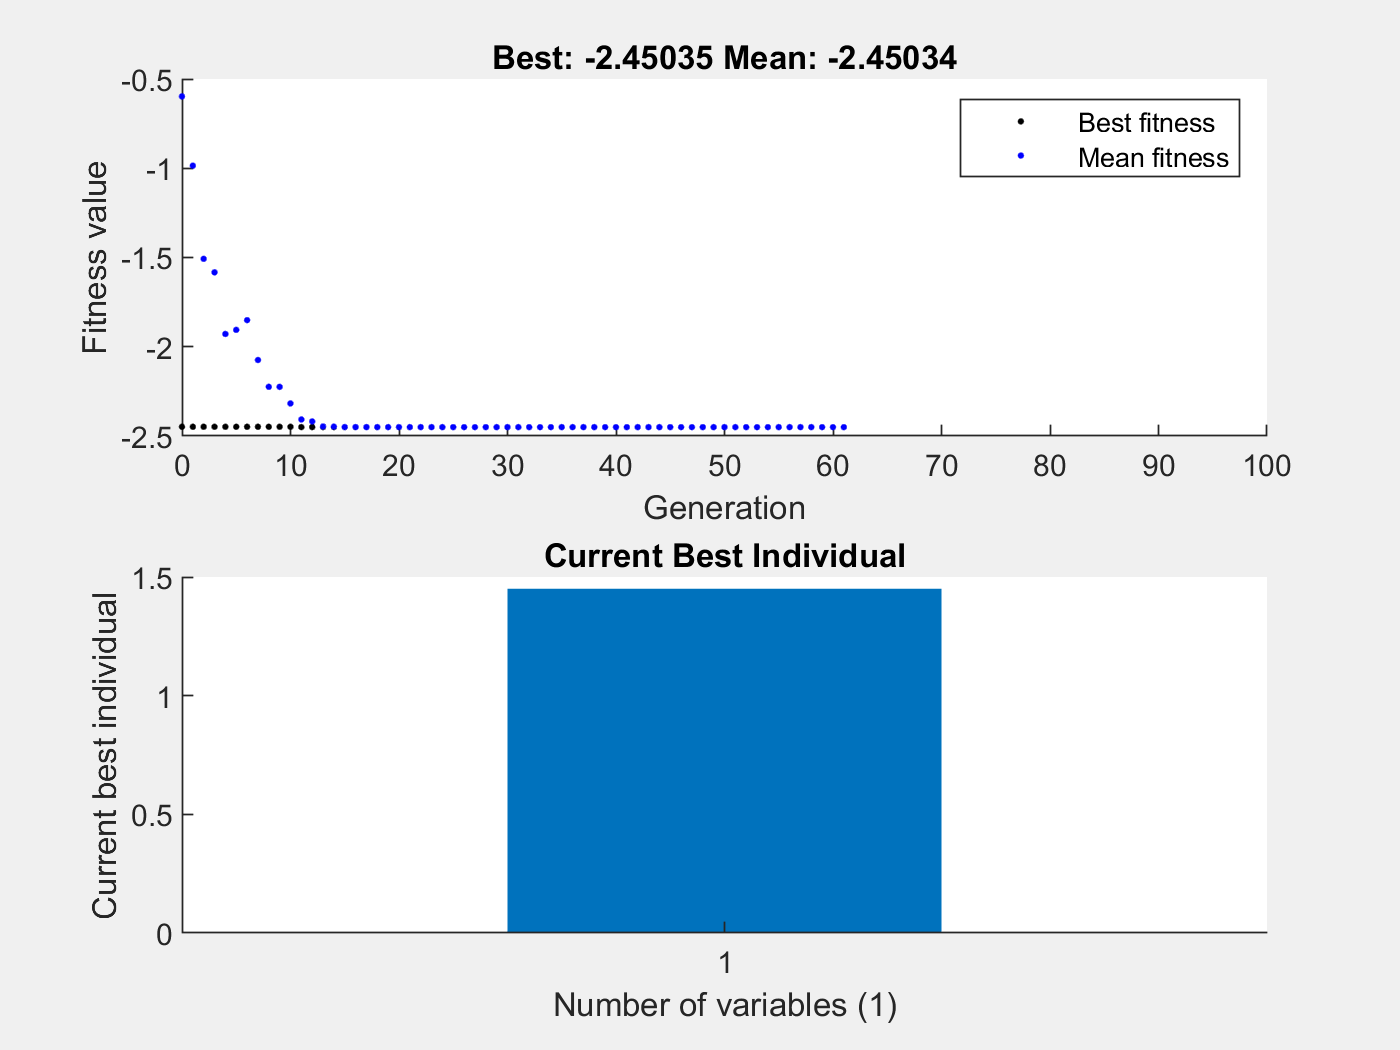

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
% En este caso, queremos maximizar f(x) = x * sin(10 * pi * x) + 1
% Dado que ga() en MATLAB minimiza, maximizamos multiplicando por -1.
objective = @(x) -(x .* sin(10 * pi * x) + 1);

% Definir los límites de las variables (x entre 0 y 2)
lb = 0;  % Límite inferior
ub = 2;  % Límite superior

% Utilizar el solver 'ga' con opciones configuradas
% Configuración del algoritmo genético usando gaoptimset
options = gaoptimset('Display', 'iter', 'PlotFcns', {@gaplotbestf, @gaplotbestindiv});

% Ejecutar el algoritmo genético
[x_opt, fval] = ga(objective, 1, [], [], [], [], lb, ub, [], options);


% Mostrar los resultados
disp('Mejor solución encontrada (x óptimo):');

Mejor solución encontrada (x óptimo):


disp(x_opt);

    1.4506



disp('Valor de la función objetivo en x óptimo:');

Valor de la función objetivo en x óptimo:


disp(-fval);  % Cambiar signo para mostrar el valor máximo, ya que lo minimizamos

    2.4503



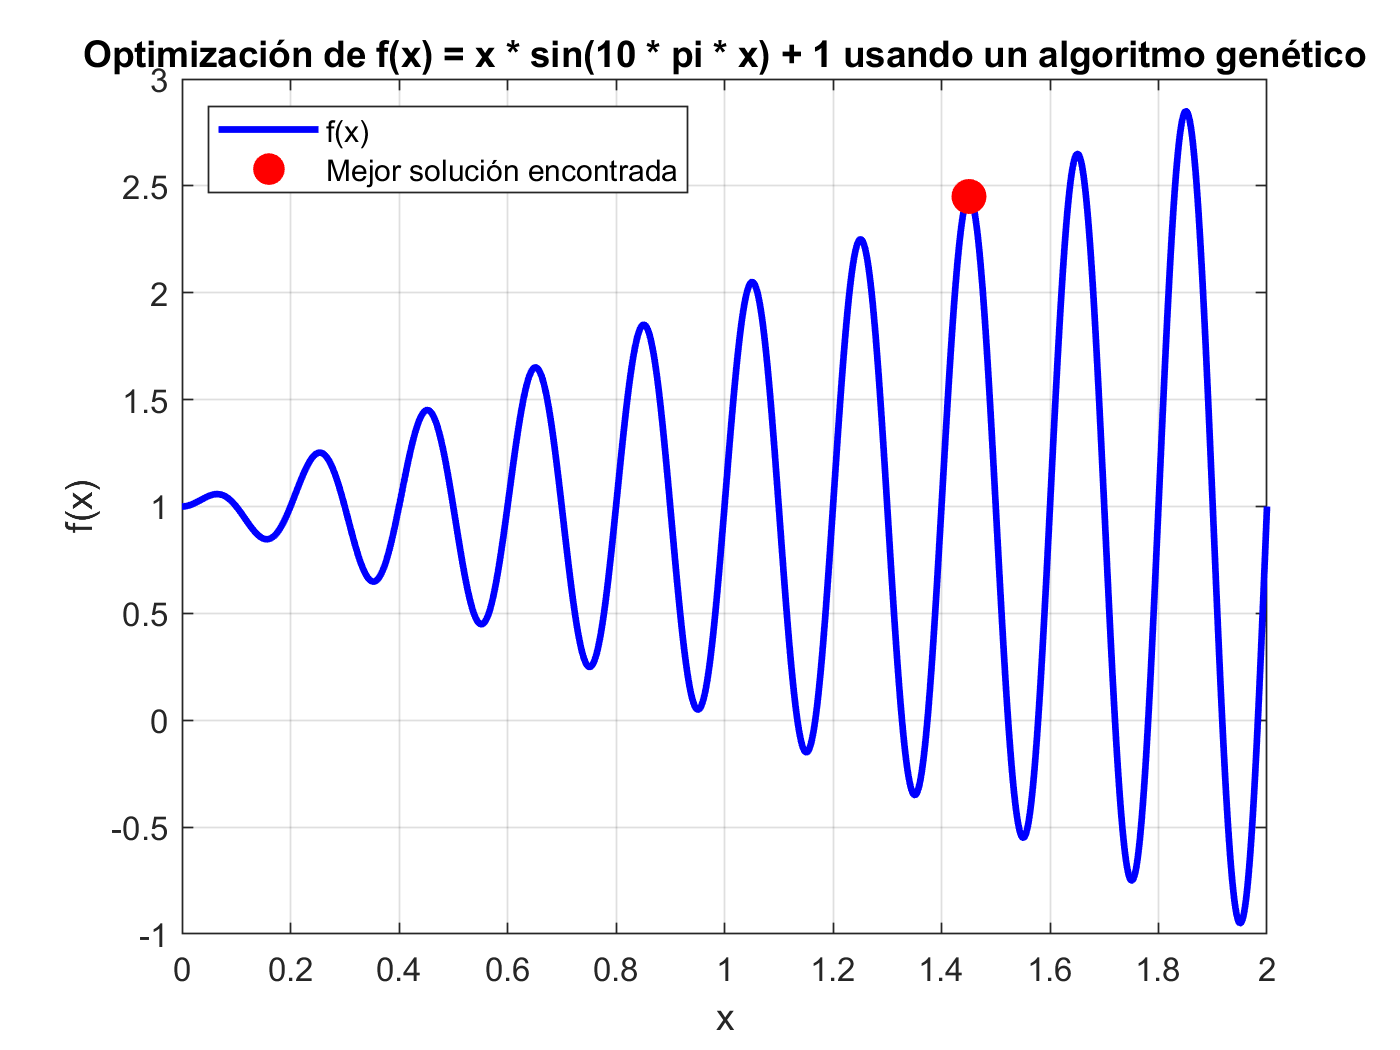


% Graficar la función original y la solución obtenida
x_values = linspace(0, 2, 1000);  % Valores de x en el rango [0, 2]
y_values = x_values .* sin(10 * pi * x_values) + 1;  % Evaluar f(x)

figure;
plot(x_values, y_values, 'b-', 'LineWidth', 2);  % Gráfico de f(x)
hold on;
plot(x_opt, -fval, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  % Punto óptimo
title('Optimización de f(x) = x * sin(10 * pi * x) + 1 usando un algoritmo genético');
xlabel('x');
ylabel('f(x)');
legend('f(x)', 'Mejor solución encontrada', 'Location', 'northwest');  % Posicionar la leyenda en la esquina noroeste
grid on;
hold off;